clc;
close all;

% Define input matrix
x = [0,0,1 ; 0,1,1 ; 1,0,1 ; 1,1,1];
x

x =      0     0     1
     0     1     1
     1     0     1
     1     1     1


% Output matrix
out_put = [0,0,0 ; 0,1,1 ; 0,1,1 ; 1,1,0];
out_put

out_put =      0     0     0
     0     1     1
     0     1     1
     1     1     0


I = 30;                                     % Number of Iterations
eta = 0.0001;                               % Learning step

% Defining initial weight matrix
w = zeros(3,3,I);                           % Preallocating weight matrix
w(:, :, 1) = 0.001 * rand(3,3);             % initial weight

% Preallocating Matrices 
out = zeros(4,3,I);                         % Output Matrix
error = zeros(4,3,I);                       % Error Matrix for each epoch 
error_AND = zeros(1,I);                     % Error Matrix for AND output 
error_OR = zeros(1,I);                      % Error Matrix for OR output 
error_XOR = zeros(1,I);                     % Error Matrix for XOR output 

% Learning Loop
for n = 1:I
    out(:,:,n) = step_function(x(:,:) * w(:,:,n));
    error(:,:,n) = out_put(:,:) - out(:,:,n);
    summation = sum(error(:,:,n));
    error_AND(n) = summation(1)^2;
    error_OR(n) = summation(2)^2;
    error_XOR(n) = summation(3)^2;
    w(:,:, n+1) = w(:,:, n) + eta *  transpose(x(:,:)) * error(:,:,n);% Updating weight matrix
end
error

error = error(:,:,1) =

    -1    -1    -1
    -1     0     0
    -1     0     0
     0     0    -1


error(:,:,2) =

    -1    -1     0
    -1     0     0
    -1     0     0
     0     0    -1


error(:,:,3) =

     0     0     0
     0     0     1
     0     0     0
     1     0    -1


error(:,:,4) =

    -1     0     0
     0     0     1
    -1     0     1
     1     0    -1


error(:,:,5) =

     0     0     0
     0     0     0
     0     0     0
     1     0    -1


error(:,:,6) =

    -1     0     0
    -1     0     1
    -1     0     1
     0     0    -1


error(:,:,7) =

     0     0     0
     0     0     1
     0     0     1
     1     0    -1


error(:,:,8) =

     0     0     0
     0     0     0
     0     0     0
     0     0    -1


error(:,:,9) =

     0     0     0
     0     0     1
     0     0     1
     0     0     0


error(:,:,10) =

     0     0    -1
     0     0     0
     0     0     0
     0     0    -1


error(:,:,11) =

     0     0     0
     0     0   

w

w = w(:,:,1) =

   1.0e-03 *

    0.0759    0.7792    0.5688
    0.0540    0.9340    0.4694
    0.5308    0.1299    0.0119


w(:,:,2) =

   1.0e-03 *

   -0.0241    0.7792    0.4688
   -0.0460    0.9340    0.3694
    0.2308    0.0299   -0.1881


w(:,:,3) =

   1.0e-03 *

   -0.1241    0.7792    0.3688
   -0.1460    0.9340    0.2694
   -0.0692   -0.0701   -0.2881


w(:,:,4) =

   1.0e-03 *

   -0.0241    0.7792    0.2688
   -0.0460    0.9340    0.2694
    0.0308   -0.0701   -0.2881


w(:,:,5) =

   1.0e-03 *

   -0.0241    0.7792    0.2688
    0.0540    0.9340    0.2694
   -0.0692   -0.0701   -0.1881


w(:,:,6) =

   1.0e-03 *

    0.0759    0.7792    0.1688
    0.1540    0.9340    0.1694
    0.0308   -0.0701   -0.2881


w(:,:,7) =

   1.0e-03 *

   -0.0241    0.7792    0.1688
    0.0540    0.9340    0.1694
   -0.2692   -0.0701   -0.1881


w(:,:,8) =

   1.0e-03 *

    0.0759    0.7792    0.1688
    0.1540    0.9340    0.1694
   -0.1692   -0.0701   -0.0881


w(:,:,9) =

   1.0e-03 *

  

out

out = out(:,:,1) =

     1     1     1
     1     1     1
     1     1     1
     1     1     1


out(:,:,2) =

     1     1     0
     1     1     1
     1     1     1
     1     1     1


out(:,:,3) =

     0     0     0
     0     1     0
     0     1     1
     0     1     1


out(:,:,4) =

     1     0     0
     0     1     0
     1     1     0
     0     1     1


out(:,:,5) =

     0     0     0
     0     1     1
     0     1     1
     0     1     1


out(:,:,6) =

     1     0     0
     1     1     0
     1     1     0
     1     1     1


out(:,:,7) =

     0     0     0
     0     1     0
     0     1     0
     0     1     1


out(:,:,8) =

     0     0     0
     0     1     1
     0     1     1
     1     1     1


out(:,:,9) =

     0     0     0
     0     1     0
     0     1     0
     1     1     0


out(:,:,10) =

     0     0     1
     0     1     1
     0     1     1
     1     1     1


out(:,:,11) =

     0     0     0
     0     1     0
     0     1     0
 

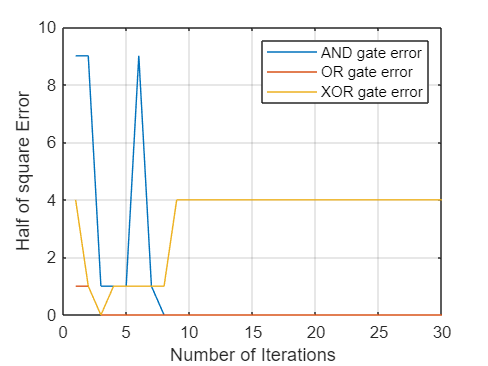

% ploting errors through Iterations
figure();
plot(1:I, error_AND);
hold on
plot(1:I, error_OR);
hold on
plot(1:I, error_XOR);
legend('AND gate error','OR gate error','XOR gate error');
xlabel('Number of Iterations');
ylabel('square Error');
grid on;


% Step function for perceptron

function [Y]= step_function(X)
Y = zeros(size(X,1),size(X,2));
for i = 1:size(X,1)
    for j=1:size(X,2)
        if X(i,j)<0
            Y(i,j)=0;
        else
            Y(i,j)=1;
        end
    end
end
end